# YOLOv4 Inference(五行code)

% Bulit on 2022.6.13 by Fred Liu

## **Tiny YOLOv4**

**載入YOLOv4模型(Tiny)**

detector = yolov4ObjectDetector("tiny-yolov4-coco");

**載入影像**

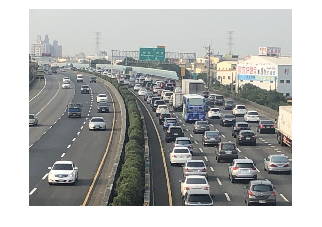

img = imread('highway.jpg'); figure,imshow(img)

**進行辨識**

[bboxes,scores,labels] = detect(detector,img);

**畫標記框與顯示**

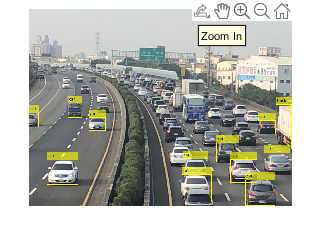

detectedImg = insertObjectAnnotation(img,"Rectangle",bboxes,labels);
figure,imshow(detectedImg)

**DarkNet53 YOLOv4**

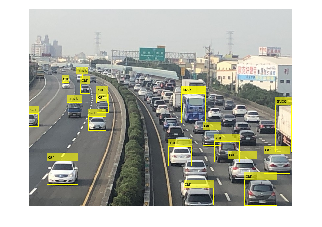

detector2 = yolov4ObjectDetector("csp-darknet53-coco");
[bboxes2,scores2,labels2] = detect(detector2,img);
detectedImg2 = insertObjectAnnotation(img,"Rectangle",bboxes2,labels2);
figure,imshow(detectedImg2)

**DarkNet53 YOLOv4 Th>0.2**

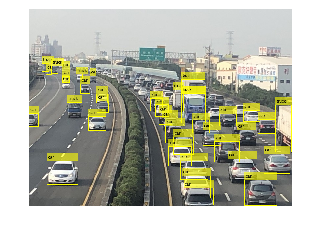

[bboxes3,scores3,labels3] = detect(detector2,img,Threshold=0.15); %'Threshold', 0.2
detectedImg3 = insertObjectAnnotation(img,"Rectangle",bboxes3,labels3);
figure,imshow(detectedImg3)